## **Worksheet 3 Gradient and Hessian and Saddle Points**

**J.Morlier March 2020**

clear all; close all;

%1.
syms x1 x2 
J=2*x1^3 +3*x2^2 +3*x2*x1^2 -24*x2

$$J = 2\,{x_{1}}^{3}+3\,{x_{1}}^{2}\,x_{2}+3\,{x_{2}}^{2}-24\,x_{2}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=[dJdx1; dJdx2]

$$dJ = \left(\begin{array}{c} 6\,{x_{1}}^{2}+6\,x_{2}\,x_{1}\\ 3\,{x_{1}}^{2}+6\,x_{2}-24 \end{array}\right)$$


Hdx1=diff(dJ,x1);

Hdx2=diff(dJ,x2);

H=[Hdx1 Hdx2]

$$H = \left(\begin{array}{cc} 12\,x_{1}+6\,x_{2} & 6\,x_{1}\\ 6\,x_{1} & 6 \end{array}\right)$$

substitute with Saddle Point (0,4);(4,-4);(-2,2)

A=subs(H,[x1 x2], [0 4])

$$A = \left(\begin{array}{cc} 24 & 0\\ 0 & 6 \end{array}\right)$$

det(A)

$$ans = 144$$

trace (A)

$$ans = 30$$

Lambda=eig(A)

$$Lambda = \left(\begin{array}{c} 6\\ 24 \end{array}\right)$$

Since both eigenvalues are positive, we conclude that the function takes a (local) minimum at p*=(x1*,x2*)=(0,4).

One can indeed confirm this by plotting the function around this point in Matlab. 

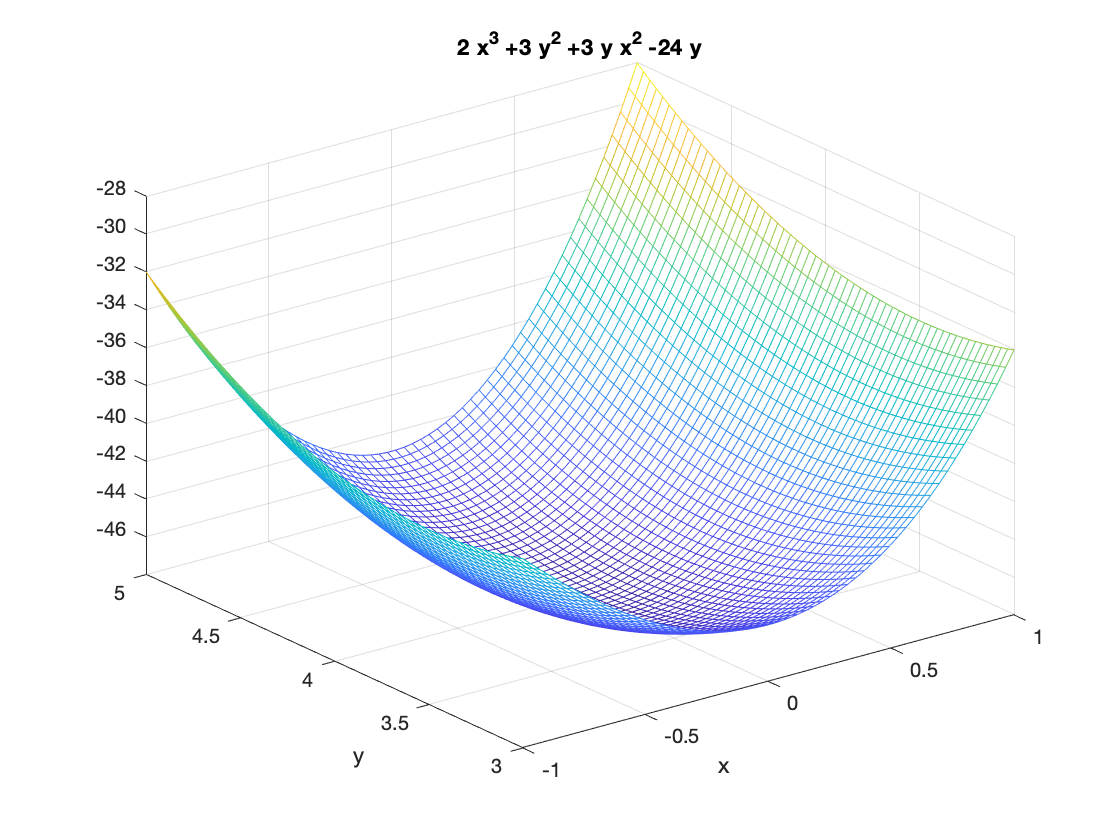

j = '2*x^3 +3*y^2 +3*y*x^2 -24*y';
ezmesh(j,[-1 1 3 5]);

%2.
syms x1 x2 
J=(x1^2 +x2^2 -1)^2 + (x2^2 -1)^2

$$J = {\left({x_{1}}^{2}+{x_{2}}^{2}-1\right)}^{2}+{\left({x_{2}}^{2}-1\right)}^{2}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=simplify([dJdx1; dJdx2])

$$dJ = \left(\begin{array}{c} 4\,x_{1}\,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right)\\ 4\,x_{2}\,\left({x_{1}}^{2}+2\,{x_{2}}^{2}-2\right) \end{array}\right)$$



Hdx1=diff(dJ,x1);

Hdx2=diff(dJ,x2);

H=[Hdx1 Hdx2]

$$H = \left(\begin{array}{cc} 12\,{x_{1}}^{2}+4\,{x_{2}}^{2}-4 & 8\,x_{1}\,x_{2}\\ 8\,x_{1}\,x_{2} & 4\,{x_{1}}^{2}+24\,{x_{2}}^{2}-8 \end{array}\right)$$

substitute with Saddle Point (0,0);etc...

A=subs(H,[x1 x2], [0 0])

$$A = \left(\begin{array}{cc} -4 & 0\\ 0 & -8 \end{array}\right)$$

det(A)

$$ans = 32$$

trace (A)

$$ans = -12$$

Lambda=eig(A)

$$Lambda = \left(\begin{array}{c} -8\\ -4 \end{array}\right)$$

Since both eigenvalues are negative, we conclude that the function takes a (local) maximum at p*=(x1*,x2*)=(0,0).

One can indeed confirm this by plotting the function around this point in Matlab. 

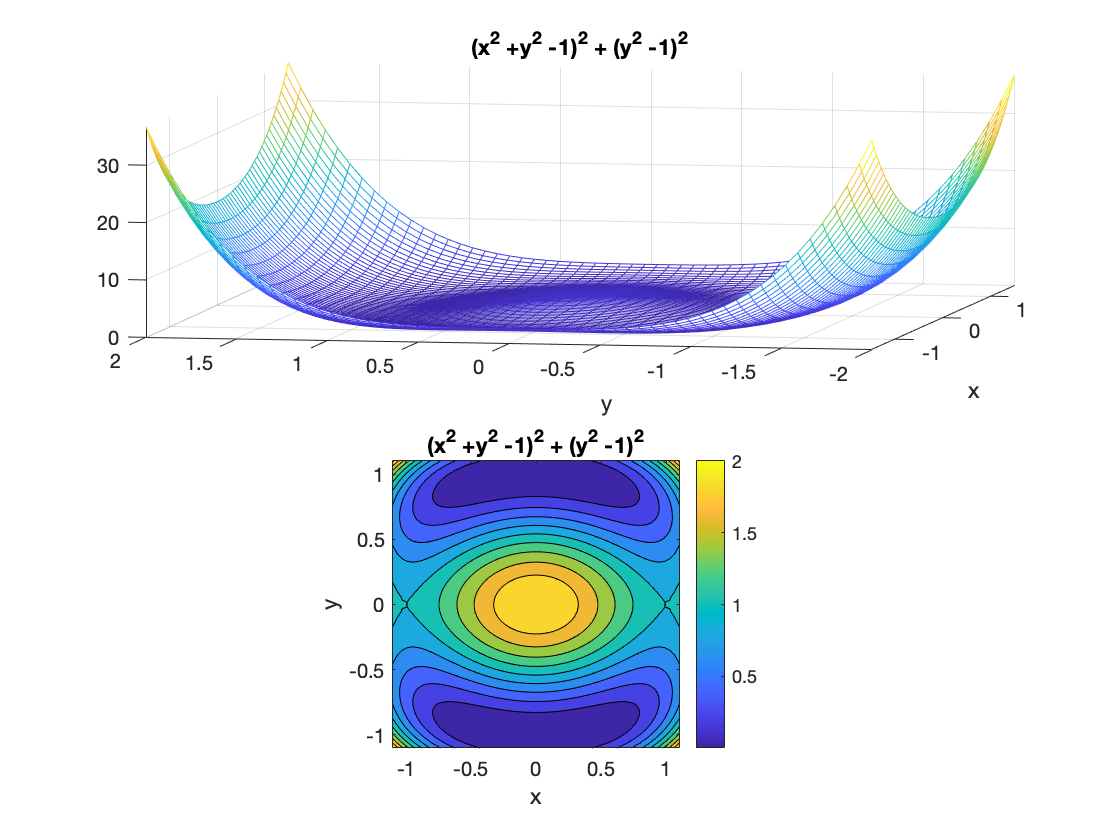

j = '(x^2 +y^2 -1)^2 + (y^2 -1)^2';
subplot(211);ezmesh(j,[-1.5 1.5 -2 2]);
view([-78.9 17.4])
subplot(212);ezcontourf(j,[-1.1 1.1 -1.1 1.1]);colorbar;axis equal;




%3.
syms x1 x2 
J=-2*x1^2 +x1*x2^2 +4*x1^4 

$$J = 4\,{x_{1}}^{4}-2\,{x_{1}}^{2}+x_{1}\,{x_{2}}^{2}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=[dJdx1; dJdx2]

$$dJ = \left(\begin{array}{c} 16\,{x_{1}}^{3}-4\,x_{1}+{x_{2}}^{2}\\ 2\,x_{1}\,x_{2} \end{array}\right)$$



Hdx1=diff(dJ,x1);

Hdx2=diff(dJ,x2);

H=[Hdx1 Hdx2]

$$H = \left(\begin{array}{cc} 48\,{x_{1}}^{2}-4 & 2\,x_{2}\\ 2\,x_{2} & 2\,x_{1} \end{array}\right)$$



%4.
syms x1 x2 
J=(x1+x2)/(x1^2 +x2^2 +1)

$$J = \frac{x_{1}+x_{2}}{{x_{1}}^{2}+{x_{2}}^{2}+1}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=[dJdx1; dJdx2]

$$dJ = \left(\begin{array}{c} \frac{1}{{x_{1}}^{2}+{x_{2}}^{2}+1}-\frac{2\,x_{1}\,\left(x_{1}+x_{2}\right)}{{\left({x_{1}}^{2}+{x_{2}}^{2}+1\right)}^{2}}\\ \frac{1}{{x_{1}}^{2}+{x_{2}}^{2}+1}-\frac{2\,x_{2}\,\left(x_{1}+x_{2}\right)}{{\left({x_{1}}^{2}+{x_{2}}^{2}+1\right)}^{2}} \end{array}\right)$$



Hdx1=diff(dJ,x1);

Hdx2=diff(dJ,x2);

H=simplify([Hdx1 Hdx2])

$$H = \begin{array}{l} \left(\begin{array}{cc} -\frac{2\,\left(-{x_{1}}^{3}-3\,{x_{1}}^{2}\,x_{2}+3\,x_{1}\,{x_{2}}^{2}+3\,x_{1}+{x_{2}}^{3}+x_{2}\right)}{\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & -\frac{2\,\left({x_{1}}^{3}+3\,{x_{1}}^{2}\,x_{2}-3\,x_{1}\,{x_{2}}^{2}+x_{1}-{x_{2}}^{3}+3\,x_{2}\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{2\,\left({x_{1}}^{3}-3\,{x_{1}}^{2}\,x_{2}-3\,x_{1}\,{x_{2}}^{2}+x_{1}+{x_{2}}^{3}+x_{2}\right)}{\sigma_{2}}\\ \sigma_{2}={\left({x_{1}}^{2}+{x_{2}}^{2}+1\right)}^{3} \end{array}$$